clear, clc, format short g


data = importdata("dati_punto_3.mat");
data2 = importdata("dati_punto_2.mat");

U_H = data.U_H;
U_phi = data.U_phi;
H = data.H;
phi = data.phi;
ur_H = data.ur_H;
u_phi = data.u_phi;
C_H = data2.C_H;
C_phi = data2.C_phi;

## Parte 4

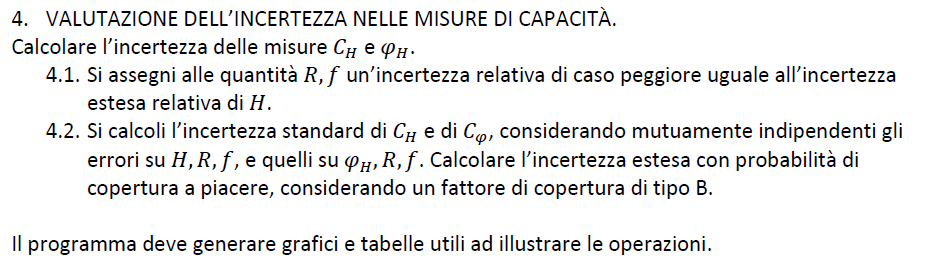

## Calcolo l'incertezza estesa relativa di C_H

% Calcolo incertezza relativa estesa sulla misura di risposta in ampiezza
Ur_H = U_H/abs(H)

Ur_H =     0.0051436



% Imposto l'incertazza relativa di caso peggiore
Ur_100_R = Ur_H;
Ur_100_f = Ur_H;

% Calcolo simbolico dei coefficienti di sensibilità relativi per la mkisura
% di capacità in ampiezza

syms C_H_sym R_sym f_sym H_sym C_phi_sym phi_sym x1_sym x2_sym CrH_sym CrPhi_sym as real

% definisco la funzione di calcolo della capacità nota la risposta in
% ampiezza
C_H_sym = sqrt(1 - H_sym^2)/H_sym*(1/(2*pi*R_sym*f_sym))

$$C\_H\_sym = \frac{\sqrt{1-{H_{\mathrm{sym}}}^{2}}}{2\,H_{\mathrm{sym}}\,R_{\mathrm{sym}}\,f_{\mathrm{sym}}\,\pi }$$


% definisco il vettore degli ingressi per la misura di capacità
x1_sym = [H_sym R_sym f_sym]'

$$x1\_sym = \left(\begin{array}{c} H_{\mathrm{sym}}\\ R_{\mathrm{sym}}\\ f_{\mathrm{sym}} \end{array}\right)$$


% calcolo coefficienti di sensibiltà relativi
CrH_sym = simplify(jacobian(log(C_H_sym), x1_sym).*x1_sym')

$$CrH\_sym = \left(\begin{array}{ccc} \frac{1}{{H_{\mathrm{sym}}}^{2}-1} & -1 & -1 \end{array}\right)$$


% stima dell'incertezza standard, supponendo in ingresso distribuzione
% uniforme poiché note le incertezze di caso peggiore relative
ur_f = Ur_100_f/sqrt(3)

ur_f =     0.0029696


ur_R = Ur_100_R/sqrt(3)

ur_R =     0.0029696



% calcolo pratico, sostituendo ai valori simbolici i valori noti, calcolati
% precedentemente
CrH = [(1/(H^2 - 1)) -1 -1]

CrH =       -38.716           -1           -1



ur_C_H = [ur_H ur_R ur_f]

ur_C_H =     0.0026211    0.0029696    0.0029696



% stima matrice covarianza relativa in ingresso per la misura della
% capacità con risposta in ampiezza
sigmar_C_H_input = diag(ur_C_H.^2)

sigmar_C_H_input =    6.8703e-06            0            0
            0   8.8188e-06            0
            0            0   8.8188e-06



% stima matrice covarianza relativa in uscita
sigmar_C_H_output = CrH*sigmar_C_H_input*CrH'

sigmar_C_H_output =      0.010316



% stima incertezza standard in uscita
ur_CH = sqrt(diag(sigmar_C_H_output))

ur_CH =       0.10157



% stima incertezza assoluta della misura di capacità in uscita, noti
% l'incertezza relativa in uscita ed il modulo della capacità
u_CH = ur_CH * abs(C_H)

u_CH =    1.1173e-09


## Calcolo dell'incertezza relativa di C_phi

% calcolo simbolico coefficienti relativi della misura di capacità nota la
% risposta di fase
C_phi_sym = tan(-phi_sym)*(1/(2*pi*R_sym*f_sym))

$$C\_phi\_sym = -\frac{\tan\left(\varphi_{\mathrm{sym}}\right)}{2\,R_{\mathrm{sym}}\,f_{\mathrm{sym}}\,\pi }$$


x2_sym = [phi_sym R_sym f_sym]'

$$x2\_sym = \left(\begin{array}{c} \varphi_{\mathrm{sym}}\\ R_{\mathrm{sym}}\\ f_{\mathrm{sym}} \end{array}\right)$$


CrPhi_sym = simplify(jacobian(log(C_phi_sym), x2_sym).*x2_sym')

$$CrPhi\_sym = \left(\begin{array}{ccc} \frac{2\,\varphi_{\mathrm{sym}}}{\sin\left(2\,\varphi_{\mathrm{sym}}\right)} & -1 & -1 \end{array}\right)$$



% sostituisco le relazioni ottenute col calcolo simbolico usando le
% variabili calcolate prima
CrPhi = [(2*phi/sin(2*phi)) -1 -1]

CrPhi =        1.0158           -1           -1



ur_phi = u_phi / abs(phi)

ur_phi =      0.017287



ur_C_Phi = [ur_phi ur_R ur_f]

ur_C_Phi =      0.017287    0.0029696    0.0029696



% stima matrice covarianza relativa in ingresso
sigmar_C_Phi_input = diag(ur_C_Phi.^2)

sigmar_C_Phi_input =    0.00029883            0            0
            0   8.8188e-06            0
            0            0   8.8188e-06



% stima matrice covarianza relativa in uscita
sigmar_C_Phi_output = CrPhi*sigmar_C_Phi_input*CrPhi'

sigmar_C_Phi_output =    0.00032595



ur_CPhi = sqrt(diag(sigmar_C_Phi_output))

ur_CPhi =      0.018054



% calcolo incertezza relativa in uscita note la misura di capacità e
% l'incertezza relativa sulla misura ottenuta dalla risposta di fase
u_CPhi = ur_CPhi * abs(C_phi)

u_CPhi =    2.6844e-10


C_phi =    1.4868e-08


## Calcolo incertezze estese con cp = 90%

% stima incertezze estese con valutazioe di tipo B (dunque usando norminv)
k = norminv((1+0.9)/2)

k =        1.6449



U_90_C_H = k*u_CH

U_90_C_H =    1.8378e-09



U_90_C_Phi = k*u_CPhi

U_90_C_Phi =    4.4154e-10
